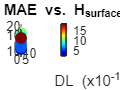

% Data (scaled DL by multiplying with 1e10 as specified)
H_surface = [5.6, 7.975, 9.1625, 6.7875, 7.38125, 9.75625, 8.56875, 6.19375, 6.490625, ...
             8.865625, 10.053125, 7.678125, 7.084375, 9.459375, 8.271875, 5.896875];
DL = [1.00000e-11, 5.05000e-10, 2.57500e-10, 7.52500e-10, 3.81250e-10, 8.76250e-10, ...
      1.33750e-10, 6.28750e-10, 3.19375e-10, 8.14375e-10, 7.18750e-11, 5.66875e-10, ...
      1.95625e-10, 6.90625e-10, 4.43125e-10, 9.38125e-10] * 1e10;  % Scale DL
MAE = [19.20508597, 4.03920771, 5.09584047, 5.15465692, 4.25503972, 10.75757148, ...
       2.44395282, 6.4148951, 5.92744258, 6.7994473, 3.26816468, 3.88493944, ...
       4.68061998, 8.86157548, 4.17551113, 6.73182634];

% Create 3D scatter plot
figure;
scatter3(H_surface, DL, MAE, 50, MAE, 'filled');  % 50 is marker size, color by MAE
colormap(jet);  % Use a colormap, e.g., 'jet'
colorbar;  % Show color scale for MAE values
xlabel('H_{surface}');
ylabel('DL (x10^{-10})');
zlabel('MAE');
title('3D Scatter Plot of MAE vs. H_{surface} and DL');
grid on;